# **ACM 11 Homework 4, Part 1: Quadrature versus Monte Carlo methods**

You should read the problem set-up in this file and follow the instructions to write and test your code. This part is independent of Part 2, you can do them in any order. When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas.

**Motivation**

It is of vital importance in the scientific or engineering practice to evaluate integrals like $\int_\Omega f(x)dx$, where $f$ is some function that doesn't necessarily have an analytical form but only supports evaluation, and the region $\Omega \subset {\mathbf{R}}^d$. Even if sometimes people are lucky enough to meet an analytical $f$, we could still have no access to a closed-form formula for the integral (for example, try finding a combination of elementary functions that evaluates $\int_{-\infty}^y e^{-x^2} dx$). 

The numerical solution to such integral $\int_\Omega f(x)dx$ consists of two approaches: a deterministic one named numerical quadrature, and a stochastic one called the Monte Carlo method. 

To start with, we clean our Workspace in MATLAB to avoid confusion.

clear; clc; close all;

### Problem 1: Numerical Quadrature

Numerical quadrature is a very classic method that estimates the integral $\int_\Omega f(x)dx$ by a weighted sum: $\int_\Omega f(x)dx \approx \sum_{i=1,2,...,n}w_i f(x_i)$. The weights $w_i$ and the abscissa $x_i$ are carefully chosen so that the estimate is accurate for a large class of simple functions $f$, such as polynomials. ("Abscissa" is a fancy way to refer to the horizontal coordinate of a graph, and is common in quadrature literature.)

Define out target functions: $f\left(x\right)=e^{x-x^2 \;\sin \left(2x\right)}$ and $g\left(x,y\right)=e^{x^2 +y-\tanh \left(2y\right)}$.

Replace the 0 in the code block below with the appropriate function.

f = @(x) exp(x - x.^2 .* sin(2.*x));
g = @(x,y) exp(x.^2 + y - tanh(2.*y));

Let the region $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. For dimension $d=1,2$, complete the skeleton code for the Gaussian quadrature rule `GQ`. Here $n$ is the number of abscissas we would have along one dimension. In other words, there are $n^d$ abscissas in total. See the notes/class slides on multivariate integrals for the appropriate formula for approximating a 2D integral.

For $n=2,3,4,5,6,7,8$, compare the output of the `GQ` function with the output of the built-in functions `integral` and `integral2` (for $d=1,2$respectively). The output of the latter functions will serve as the reference value for the true integral. You should measure the error of `GQ` with respect to the reference integral value by absolute value, and plot it against the number of total abscissas used (be careful, it should be $n^d$). Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for $x$- and $y$-axes. Include appropriate axes labels and a legend. You may find the function `loglog `helpful.

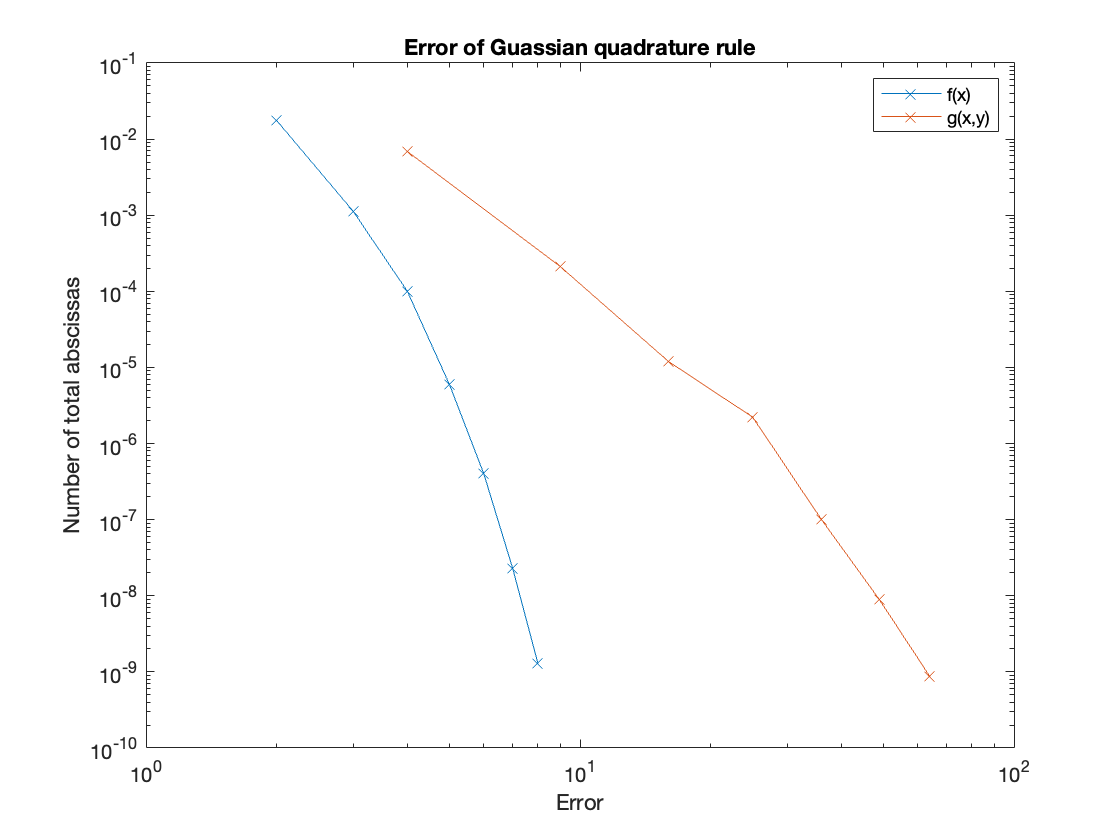

n = 2:8;
ref = zeros(2, length(n));
gq = zeros(2, length(n));

for i=1:length(n)
    ref(1, i) = integral(f, 0, 1);
    ref(2, i) = integral2(g, 0, 1, 0, 1);
    
    gq(1, i) = GQ(f, 1, n(i));
    gq(2, i) = GQ(g, 2, n(i));
    

end

error = abs(ref - gq);

figure;
loglog(n, error(1,:), "-x")
hold on
loglog(n.^2, error(2,:), "-x")
xlabel("Error")
ylabel("Number of total abscissas")
legend("f(x)", "g(x,y)", "Location", "northeast")
title("Error of Guassian quadrature rule")
hold off

How does the convergence of the quadrature estimate the integral (slope of the error) differ between these two functions? Explain your observation in terms of the integral dimension $d$.

The slope of f(x) is smoother and steeper than the slope of g(x,y) which means that f(x) converges faster. This is because for f(x) is dimension 1 therefore its n, while g(x,y) is dimension 2 so its n^2 so it will use more calculations.

### Problem 2: Monte Carlo Estimate

Another approach to estimate the integral $\int_\Omega f(x)dx$ is to write it in the expectation form: $\int_\Omega f(x)dx = |\Omega| {\bf E}_{u\sim U(\Omega)}[f(u)]$, here $|\Omega |$ is the length/area/volume of the region $\Omega$, and $u$ is a random variable that is uniformly distributed on $\Omega$. Then, we can use the Monte Carlo method to estimate this expectation. Let $u_1 ,\ldotp \ldotp \ldotp ,u_n$ be the i.i.d. samples from the uniform distribution on $\Omega$, then ${\bf E}_{u\sim U(\Omega)}[f(u)]\approx \frac{1}{n} \sum_{i=1,2,...,n}f(u_i)$. Thus we conclude that $\int_\Omega f(x) dx \approx \frac{|\Omega|}{n}\sum_{i=1,2,...,n}f(u_i)$. 

Write a function named `MCE` that takes in the function $f$, dimension $d$, and number of samples $n$, and outputs the Monte Carlo estimate. Here we assume that $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. You may use `rand` to generate a random variable uniformly distributed between 0 and 1.

**Complete the **`MCE`** function at the bottom of this file with the appropriate function.**

For $n=10,100,1000,10000$, compare the output of the `MCE` function with the built-in functions `integral` and `integral2` (for $d=1,2$ respectively). Due to the randomness, for each $n$, we want you to call `MCE` for $100$ times, and use the mean of their absolute difference with respect to the reference integral value as the error. You may find the function `mean` helpful. Plot the error against the number of total samples used. Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for both $x$- and $y$-axes. You may find the function `loglog `helpful.

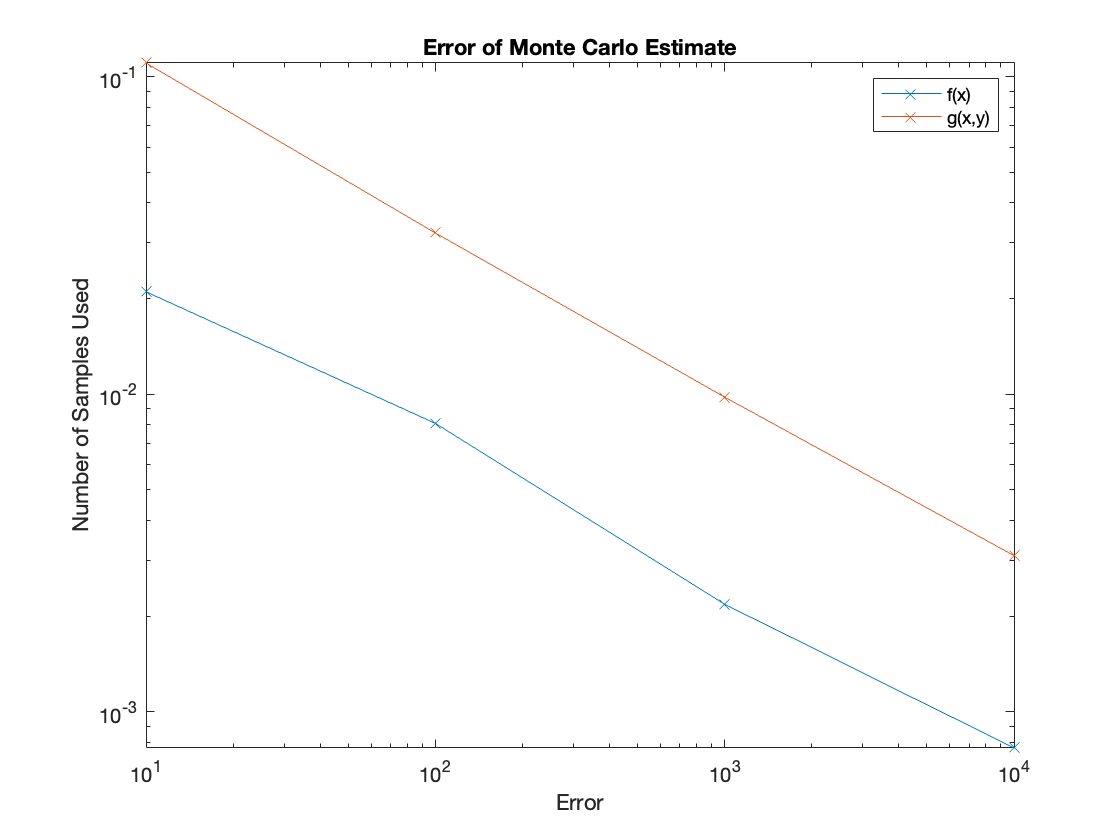

%TODO - your code here
n = [10, 100, 1000, 10000];

ref = zeros(2, length(n));
error = zeros(2, length(n));
N = 100;

for i=1:length(n)
    ref(1, i) = integral(f, 0, 1);
    ref(2, i) = integral2(g, 0, 1, 0, 1);
    mce_diff = zeros(2, N);
    
    for j=1:N
        mce_diff(1, j) = abs(MCE(f, 1, n(i)) - ref(1, i));
        mce_diff(2, j) = abs(MCE(g, 2, n(i)) - ref(2, i));
    end
    
    error(1, i) = mean(mce_diff(1, :));
    error(2, i) = mean(mce_diff(2, :));
end

figure;

loglog(n, error(1,:), "-x")
hold on
loglog(n, error(2,:), "-x")
xlabel("Error")
ylabel("Number of Samples Used")
legend("f(x)", "g(x,y)", "Location", "northeast")
title("Error of Monte Carlo Estimate")
hold off

How does the convergence of the Monte Carlo estimate of the integral (slope of the error) behave for these two functions? How is this different from the convergence behavior of the traditional quadrature approach? Is this theoretically expected?

The slope of f(x) is the same as the slope of g(x,y). This is different from the traditional quadrature approach because in that approach the slope of g(x,y) was less steep, additionally in this approach both lines are linear while in the traditional quadrature approach the lines are not linear. This is theoretically expected because they have the decay of the Monte Carlo depends on n not on n^d, so it will be the same slope no matter the d.

function I = MCE(func,d,n)
assert(d==1|d==2,"Invalid dimension")

u = rand(1, n);
% in this case omega = 1 so we don't have to worry about it
if d==1
    I = sum(func(u) / n);
else
    v = rand(1, n);
    I = 0;
    for i=1:n
        I = I + func(u(i), v(i));
    end
    I = I / n;
end
end

Please report the number of hours you spent on this part of the homework: 4 hours